elb = 0.12

elb = 0.1200

## Do not Touch !!!

folder = "D:\SPMDATAActive";
fn = findRecentFile(folder,'.dat')

ans = 6

fn = "D:\SPMDATAActive\Z-Spectroscopy00395.dat"

ans = 6

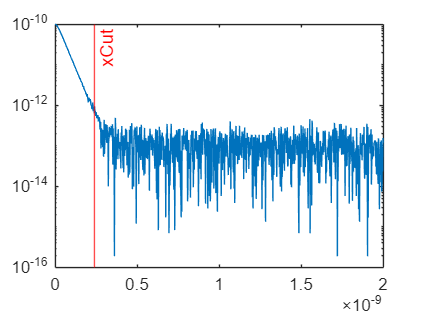

f = 4.5077

f = getWF(fn,elb)

function fn = findRecentFile(folder,fileNameExtension)
flist = dir(folder);% 폴더에 모든 파일 불러오기
flist  = struct2table(flist);
flist = flist(:,["name","date","datenum"]);
isdat = contains(string(flist{:,"name"}),fileNameExtension);
flist = flist(isdat,:);
flist = sortrows(flist,'datenum','descend');
fileNow = flist(1,:);6
fn = folder +'\'+fileNow{1,1}{1};

end

function wf = getWF(fn,elb)
%determine Elbow
[header, data, channels] = loaddat(fn);
x = data(:,1);
y = abs(data(:,2));
xcut = quantile(x,elb);6
[~,argXcut] = min(abs((x-xcut)));
plot(x,y)
yscale log;
xline(xcut,'r','xCut');

%Linear fitting
xEff = x(1:argXcut);
lyEff = log(y(1:argXcut));
result = fitlm(xEff,lyEff);
pred = result.predict(xEff);

%determine WF
me = 9.1093837*10^(-31); % Electron Mass (kg)
hbar = 1.054571817*10^(-34); % Planck Constant (J/s)
a = result.Coefficients.Estimate(2);
qe = 1.60217663 * 10^(-19);
phiV = ((a*hbar)^2)/(8*me);
wf = phiV/qe;
end

function [header, data, channels] = loaddat(fn)
% loaddat  Nanonis DAT ASCII file loader
%   [header, data, channels] = loaddat(fn) reads a Nanonis 
%   DAT ASCII file fn.
%   fn: path of the .dat file to read.
%   header: header info of the data file.
%   data: contains the data of all channels, each column in the
%       data array corresponds to an acquired channel.
%   channels: contains the names of the data channels.

data=''; header=''; channels='';

if exist(fn, 'file')
    fid = fopen(fn, 'r', 'ieee-be');    % open with big-endian
else
    fprintf('File does not exist.\n');
    return;
end

% read header data
% The header consists of key-value pairs, separated by a tab character
% e.g. Settling time (s)	200E-6	
% The beginning of the data block starts with [DATA]
while 1
    s = strtrim(fgetl(fid));
    if strcmp(upper(s),'[DATA]')
        break
    end
    
    %s1 = strsplit(s,char(9));  % not defined in older Matlab versions
    s1 = strsplit_i(s,char(9));
    s1_s = prod(size(s1));
    if s1_s > 0 % line contains a tab
        s_key = strrep(lower(s1{1}), ' ', '_');
        s_val = '';
        if s1_s > 1
            s_val = strrep(s1{2}, '"', '');
        end
        
        s_key = regexprep(lower(s_key), '[^a-z0-9_]', '_');
        header.(s_key) = s_val;
    end
end

% read the channel names
s = strtrim(fgetl(fid));
%channels = strsplit(s,'=');  % not defined in older Matlab versions
channels = strsplit_i(s,char(9));

% read the data
data = fscanf(fid, '%f', [prod(size(channels)) Inf]);
data = transpose(data);

fclose(fid);
end


function s = strsplit_i(str, delim)
    s = {};
    while ~isempty(str),
        [t,str] = strtok(str, delim);
        s{end+1} = t;
    end
end